### 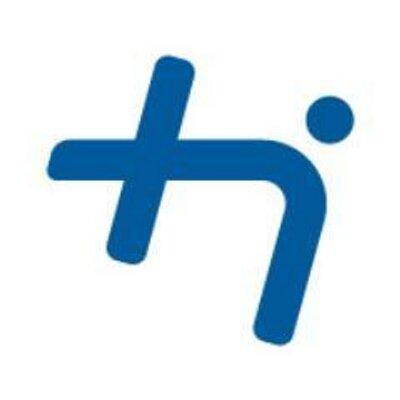**Prof. Dr. Michael Mecking **

#### **Practical Course - Digital Signal Processing / AVE **

# **Convolution**

Given a linear, time invariant (LTI) system with impulse response $h[n]$, the output signal $y[n]$ can be evaluated based on the input signal $x[n]$ by the convolution sum

$y[n] = \sum_{k=-\infty}^{\infty} x[k] \, h[n-k] =: x[n] * h[n]$.

In case the system is causal, the impulse response $h[n]$ is zero for negative $n$. In case the input signal $x[n]$ is also a causal signal, i.e., zero for negative $n$, the output can be computed by the relationship

$y[n] = \sum_{k=0}^n x[k] \, h[n-k]$.

Using MATLAB, the standard unit impulse signal $\delta[n]$ is simply described as $x=[1]$. A rectangular signal $x[n]$ of five unit samples is described by $x = [1 1 1 1 1]$. 

### **Problem 1.1**

Write your own function *my_conv* to evaluate a convolution $y[n]$ of two causal, finite duration signals $x[n]$ and $h[n]$. 

Make your mind up about the **duration** of the convolution of two finite duration signals $x$ and $h$. If the duration of $x$ and $h$ are $L_x$ and $L_h$, respectively, what is the duration $L_y$ of $y$?

Work out your code for this setup. Assume that both the signal as well as the impulse repsonse "start" at $n=0$, i.e., assume a causal signal and system. Mind: In MATLAB, this first sample is the first component $x[1]$ in the vector $x$ representing the input.

% convolution of two finite duration signals x and h 
% (both starting at n=0)
x = [1 2 3 4];
h = [1 1/2 -1 -1/2 -1];
%y=my_conv(x,h);
% your code...
%function [y]= my_conv(x,h)
y =my_conv(x, h);

Unrecognized function or variable 'my_conv'.

%end


### Problem 1.2

Verify that the minimum of the signal $y[n]$, $\min y[n] = -7.5$, occurs at $n=5$.

In case your code works, **refactor** it into a function *my_conv* for later use (you will store a local my_conv.mlx file with your MATLAB code. Mark the part of the code that should become the function and click **Refactor** in the menu bar. Follow MATLAB's guidance (in case, modify appropriately) to set up the usage of your function *my_conv*.

The function can then be used whenever your present working directory (command *pwd* in the Command Window) is the same as the location you store your file). 

### Problem 1.3

Verify your code once more by inspecting that the convolution of a signal $x[n]$ with a delayed unit impulse $\delta[n-n_d]$ is equivalent to delaying the signal by $n_d$ samples.

% delay by convolution with unit impulse
nd = 3;

% create a delayed impulse and evaluate the convolution x*h
% your code.
delta=zeros(1,nd+1)

delta =      0     0     0     0


delta(nd+1) =1

delta =      0     0     0     1



y=my_conv(x,delta)

y =      0     0     0     0     0     0     0


y =      0     0     0     1     2     3     4


**Observation: **

# **MOVING-AVERAGE SYSTEM**

The moving-average system is to be analysed. A moving average system applies a sliding rectangular window over the input sequence. It's output is the average value of the signal samples $x[n]$ within it's sliding window.

The input/output-relationship of the moving-average system is given by 

$y[n] = \frac{1}{M_1 + M_2 + 1} \, \sum_{k=-M_1}^{M_2} x[n-k]$.

Hence, the impulse response $h[n]$ of the moving-average system is given by 

$h[n] = \frac{1}{M_1 + M_2 + 1}$ for $-M_1 \le n \le M_2$ and $0$ otherwise.

In case the system ought to be causal, $M_1 = 0$.

The following signal $x[n]$ consisting of seven consecutive sine-signals of increasing frequencies will be used. The sampling frequency is fixed at $f_S = 8$ kHz.

% generate seven cosines with frequencies equally spaced within 
% the resolvable frequency band
fs = 8000;
f0 = (1 : 1 : 7)/8 * fs/2;

% samples of each cosine will be taken for half a second, i.e., fs/2 samples.
x = [];
n = 1 : 1 : fs/2;

for k = 1:1:7
    % take half a second of a sine signal using frequency f0(k)
    x_new = sin( 2*pi * f0(k)/fs * n );

    % append new signal to previous signals
    x = [x x_new];
end

### Problem 2.1

Use the moving average system with $M_1 = 0$ and $M_2=8$ to filter the audio signal $x[n]$. 

Generate the impulse response $h_1[n]$ of the moving-average system and use your *my_conv* function to compute the system output signal $y_1[n]$ given the input signal $x[n]$.

What is the result when comparing the original to the filtered signal? Provide an interpretation by listening to the original signal $x[n]$ and the filtered signal $y_1[n]$.

You may modify the window limit $M_2$ and observe the changes in the output signal. Have a look at $M_2 = 7$ as well. $M_2 = 14, 15, 16$ are also good choices for a comparison.

% apply moving average system to the audio signal x[n]
M1 = 0;
M2 = 15;

% your code...
h1=1/(M1+M2+1)

h1 = 0.0625

y=my_conv(x,h1)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y =     0.0239    0.0442    0.0577    0.0625    0.0577    0.0442    0.0239    0.0000   -0.0239   -0.0442   -0.0577   -0.0625   -0.0577   -0.0442   -0.0239   -0.0000    0.0239    0.0442    0.0577    0.0625    0.0577    0.0442    0.0239    0.0000   -0.0239   -0.0442   -0.0577   -0.0625   -0.0577   -0.0442   -0.0239   -0.0000    0.0239    0.0442    0.0577    0.0625    0.0577    0.0442    0.0239    0.0000   -0.0239   -0.0442   -0.0577   -0.0625   -0.0577   -0.0442   -0.0239   -0.0000    0.0239    0.0442


sound(y,fs)
pause(5)
sound(y)

**Interpretation:**

### Problem 2.2

Slightly modify the moving average system and observe the output of a new system:

Use an impulse response $h_2[n]$ that is of opposite sign for the odd discrete-time instants:

$h_2[n] = (-1)^n \, h_1[n]$.

For example, if $M_1=0$ and $M_2 = 2$, the moving average filter in 2.1 computes $y[n] = \frac{1}{3} (x[n] + x[n-1] + x[n-2])$ but this filter here computes $y[n] = \frac{1}{3} (x[n] - x[n-1] + x[n-2])$.

Listen to the output signal $y_2[n]$ with this new filter $h_2[n]$ and comment on the result.

% apply modified moving average system to the audio signal x[n]
M1 = 0;
M2 = 15;
lx=length(x)

lx = 28000

% your code...
for i= 1:length(M2)
 h2(i)=(-1)^i * h1(i)
end

h2 =    -0.0625   -0.1111    0.1111   -0.1111    0.1111   -0.1111    0.1111   -0.1111    0.1111


y2=my_conv(x,h2)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y2 =    -0.0239   -0.0867   -0.0938   -0.1291   -0.1022   -0.1023   -0.0443   -0.0221    0.0460    0.1071    0.1519    0.1736    0.1689    0.1384    0.0869    0.0221   -0.0460   -0.1071   -0.1519   -0.1736   -0.1689   -0.1384   -0.0869   -0.0221    0.0460    0.1071    0.1519    0.1736    0.1689    0.1384    0.0869    0.0221   -0.0460   -0.1071   -0.1519   -0.1736   -0.1689   -0.1384   -0.0869   -0.0221    0.0460    0.1071    0.1519    0.1736    0.1689    0.1384    0.0869    0.0221   -0.0460   -0.1071


sound(y2,fs)
pause(5)
sound(y,fs)

**Comments:**

### **Problem 2.3**

The frequency response of a discrete-time filter with impulse response $h[n]$ is given by


$$H(e^{j\Omega}) = \sum_{n=-\infty}^{\infty} h[n] \, e^{-j \Omega n} .$$


Evaluate the frequency responses $H_1{e^{j\Omega})$ and $H_2(e^{j\Omega})$ of the two moving average systems considered above using the code below (check the code below).

How can you explain the observed filter behaviour using the frequency response graphs?

In particular, how can you explain the strange properties of the moving average filter for $M_1 = 0$ and $M_2 = 7$ and $M_2 = 15$ for the special signal in use?

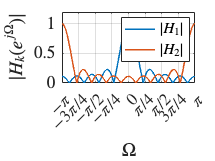

% evaluation of the frequency response of the moving-average system
% setup of variables
M1 = 0;
M2 = 8;

h1 = 1/(M1+M2+1) * ones(1, M1+M2+1);
n  = 0:1:length(h1)-1;
h2 = (-1).^n .* h1;

% frequency response along the unit circle (from -pi to pi):
num   = 512;
Omega = linspace(-pi, pi, num);

% evaluation of the frequency response H1 
helper1 = exp(-j * n' * Omega);
helper2 = h1' * ones(1, num);
H1 = sum( helper1 .* helper2 );

% ... and H2
helper2 = h2' * ones(1, num);
H2 = sum( helper1 .* helper2 );

% plot the magnitude responses of H1 and H2
plot(Omega, abs(H1), 'LineWidth', 1.5)
hold on
plot(Omega, abs(H2), 'LineWidth', 1.5)
axis([-pi pi 0 1.2])
xticks([-pi -3/4*pi -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
xticklabels({'$-\pi$','$-3\pi/4$','$-\pi/2$', '$-\pi/4$', '$0$', '$\pi/4$', '$\pi/2$', '$3\pi/4$', '$\pi$'})
set(gca,'TickLabelInterpreter', 'latex')
grid
set(gca,'FontSize', 17)
xlabel("$\Omega$", Interpreter="latex")
ylabel("$|H_k(e^{j\Omega})|$", Interpreter="latex")
legend("$|H_1|$", "$|H_2|$", Interpreter = "latex")
hold off

**Observation:**